
% 在程序开始时关闭警告
warning('off', 'MATLAB:structOnObject');

% heat_conduction --- 热传导问题求解主程序
clear; clc; close all;

time_begin = tic;

dim = 2;

ncx = 100;
ncy = 100;
ncz = 6;

xmin = 0;
xmax = 0.833;
ymin = 0;
ymax = 0.83;
zmin = 0;
zmax = 1;


% 创建网格对象
mesh = structured_mesh();
mesh = mesh.create_mesh(dim, ncx, ncy, ncz, xmin, xmax, ymin, ymax, zmin, zmax );

调试：2D网格检测成功，ncz 已设置为 1
=== 结构化网格信息 ===
维度: 2D
单元数: 100 (x) × 100 (y) × 1 (z)
节点数: 101 (x) × 101 (y) × 2 (z)
网格间距: dx=0.008330, dy=0.008300, dz=1.000000
计算域范围: x=[0.000, 0.833], y=[0.000, 0.830]



T = 373;
mesh = mesh.set_initial_t(T);
mesh = mesh.create_field_data();
mesh = mesh.create_coefficient_data();


nsteps = 1e4;
mesh = mesh.set_nsteps(nsteps);
niter_t = 10; relax_t = 0.9; 
% 残差范数每一轮（niter_t次）迭代的变化量小于该轮迭代开始时残差范数的res_t倍
res_t = 1e-2;    
% 残差范数减小到初始值的temp_tol倍以下
temp_tol = 1e-4;    
mesh = mesh.set_temperature_solver_param(niter_t, relax_t, res_t, temp_tol);

fluid_properties = fluid_properties(mesh);
dens = 1.0; mu = 1e-3; con_val = 81.0; spheat_val = 1.0;
fluid_properties = fluid_properties.set_initial_fluid(dens, mu, con_val, spheat_val);

=== 流体属性信息 ===
网格尺寸: 100 × 100 × 1
密度场范围: [1.000, 1.000]
粘度场范围: [0.001, 0.001]
传导系数: 81.000000
比热: 1.000000
热源: 0.000000



% 当前代码
boundary = boundary(mesh);

% 应该添加边界条件设置(constant或者heatflux(流出为正))
boundary = boundary.create_faces_of_cells(mesh);
boundary = boundary.create_boundary_fluid(dim, 'wall', 'wall', 'wall', 'wall', 'wall', 'wall');
boundary = boundary.create_boundary_temp(dim, ...
    'xmin', {'constant', 373.15}, ...
    'xmax', {'constant', 373.15}, ...
    'ymin', {'constant', 373.15}, ...
    'ymax', {'constant', 293.15}, ...
    'zmin', {'constant', 373.15}, ...
    'zmax', {'constant', 373.15});

=== 边界条件信息 ===
边界标识符: 
  xmin: 1, xmax: 2
  ymin: 3, ymax: 4
  zmin: 5, zmax: 6

流体边界条件:
  xmin: 壁面
  xmax: 壁面
  ymin: 壁面
  ymax: 壁面

温度边界条件:
  xmin: 定温 (T=373.150)
  xmax: 定温 (T=373.150)
  ymin: 定温 (T=373.150)
  ymax: 定温 (T=293.150)



time_end = toc(time_begin);
fprintf('网格划分时间: %.6f 秒\n', time_end);

网格划分时间: 0.084419 秒



%% 创建后处理对象和输出设置
post = post_processing();
res_freq = 1e3;
out_freq = 5e3;
post = post.Set_res_out_freq(res_freq, out_freq);

% 打开残差文件
nonlinsol_fname = post.nonlinsol_fname;
linsol_fname = post.linsol_fname;

% 打开非线性求解残差文件
nonlinsol_fid = fopen(nonlinsol_fname, 'w');
fprintf(nonlinsol_fid, "#it, walltime, l2_t/l2_max_t\n");
fclose(nonlinsol_fid);

% 打开线性求解残差文件
linsol_fid = fopen(linsol_fname, 'w');
fprintf(linsol_fid, "#it_nl, it, tot_it, norm, init, max, rel\n");
fclose(linsol_fid);

%% 开始仿真迭代
for it = 1:nsteps
    % 输出迭代信息
    if mod(it, res_freq) == 0 || it == 1 || it == nsteps

    end
    
    % 调用分离求解器
    [mesh.stop_sim, l2_t_over_l2_max_t] = collocated_segregated.solve(it, mesh, fluid_properties, boundary, post);
        
    % 输出残差信息
    if it == 1 || mod(it, res_freq) == 0 || it == nsteps || mesh.stop_sim
        elapsed_time = toc(time_begin);
        fprintf("walltime, l2_t/l2_max_t : %.6f, %.6e\n", ...
            elapsed_time, l2_t_over_l2_max_t);
        fprintf('----------------------------\n');
        
        % 写入非线性残差文件
        nonlinsol_fid = fopen(nonlinsol_fname, 'a');
        fprintf(nonlinsol_fid, "%d %.6f %.6e\n", it, elapsed_time, mesh.norm2_temp/mesh.norm2_max_temp);
        fclose(nonlinsol_fid);
        
        % 检查收敛条件
        if mesh.stop_sim
            break;
        end
    end
end

it_nl, it, tot_it, norm2, max, rel_norm, : 1, 10, 10, 2.989234e+00, 2.563805e+01, 1.165937e-01, 

walltime, l2_t/l2_max_t : 0.130785, 1.000000e+00


----------------------------


it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 10, 10000, 1.497508e-03, 1.503509e-03, 9.960085e-01, 

walltime, l2_t/l2_max_t : 9.665408, 2.202285e-04


----------------------------



----------------------------
Final iter = 1178
it, l2_t/l2_max_t: 1178, 9.988351e-05
----------------------------


walltime, l2_t/l2_max_t : 11.364943, 9.988351e-05


----------------------------



%% 计算总运行时间
total_time = toc(time_begin);
fprintf("总运行时间: %.6f 秒\n", total_time);

总运行时间: 11.372264 秒


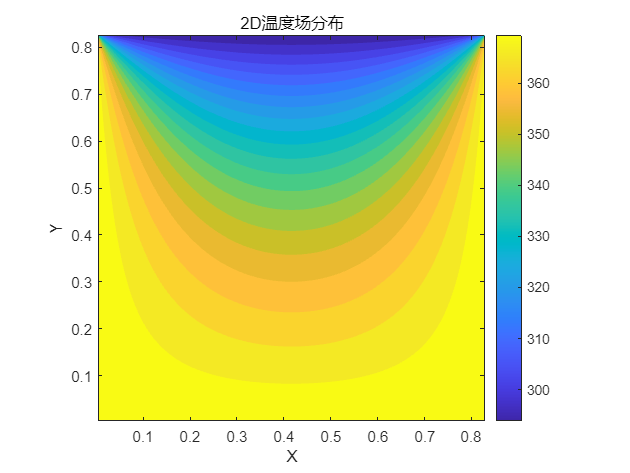

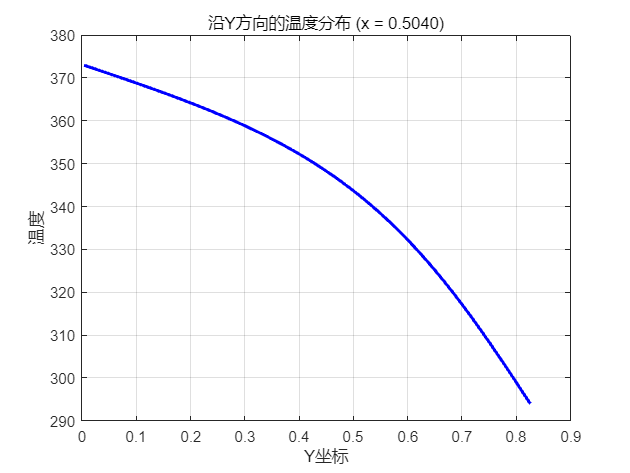

温度分布已输出到文件: temp_x05.dat


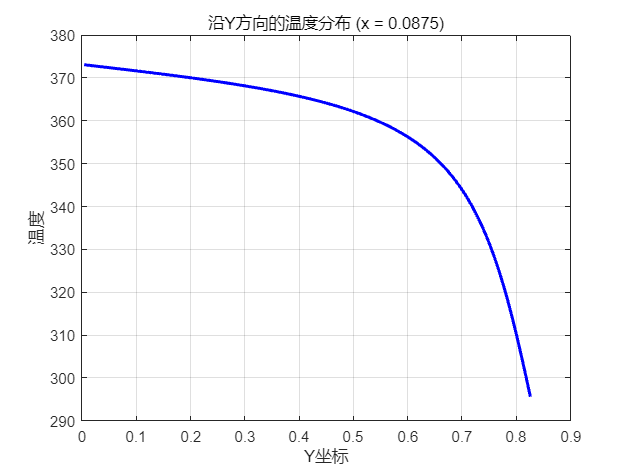

温度分布已输出到文件: temp_y00833.dat



%% 后处理可视化
if dim == 2
    % 2D情况
    % 输出2D平面的温度分布
    post.plot_temperature_2D(mesh);
    
    % 输出指定线的温度分布
    % 示例: 在x=0.5位置输出沿y方向的温度分布
    post.output_temperature_profile(mesh, 'x', 0.5, 'temp_x05.dat');
    
    % 示例: 在x=0.0833位置输出沿y方向的温度分布
    post.output_temperature_profile(mesh, 'x', 0.0833, 'temp_y00833.dat');
else
    % 3D情况 - 输出指定面的温度分布
    % 示例: 在x=0.5位置输出yz平面的温度分布
    post.output_temperature_profile(mesh, 'x', 0.5, 'temp_x_3D.dat');

    % 示例: 密集切片体绘制
    post.plot_temperature_3D_dense_slices(mesh);

end



fprintf('仿真完成！\n');

仿真完成！



% 在程序结束时恢复警告
warning('on', 'MATLAB:structOnObject');



